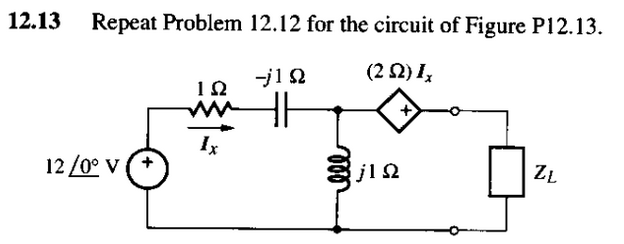

hallando voltaje de tyhevenin

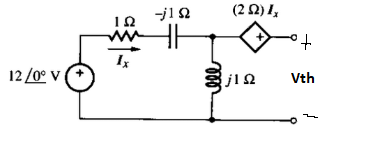

Definimos las impedancias del circuito, sabiemos que en la fuente dependiente de corriente no vamos a tener correinte 

clc, clear ,close all
format short g

vf = 12;

z1 = 1;
z2 = -j;
z3 = j;
z4 = 2;

zeq = z1+z2+z3

zeq =      1


Ix = 12/zeq

Ix =     12


conociendo la correinte Ix podemos saber la tension en la fuente depéndiente

v1 = Ix*z1

v1 =     12


v2 = Ix*z2

v2 =             0 -         12i


v3 = Ix*z3

v3 =             0 +         12i


v4 = z4*Ix

v4 =     24


LkT

Vth = v4 + v3

Vth =            24 +         12i


**Corriente de norton**

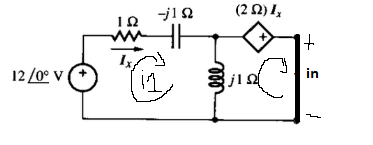

syms i1 i2

ec1= simplify(vf+(z1*i1)+(z2*i1)+z3*(i1-i2) == 0)

$$ec1 = i_{1}+12=i_{2}\,\mathrm{i}$$

ec2 = simplify(-z3*(i2-i1)-z4*i2 == 0)

$$ec2 = i_{1}\,\mathrm{i}=i_{2}\,\left(2+\mathrm{i}\right)$$

m = [(-z1-z2-z3) z3; -z3 (z3-z4)];
n = [vf;0];
h = m\n

h =           -18 -          6i
           -6 +          6i


In = h(2)

In =            -6 +          6i


Ahora quetenos la tension thevenin y corriente de norton, puedo encontrar la z thevenin

zth = Vth/In

zth =            -1 -          3i


luego sabemos que **la impedancia de carga** es igual a la conjugada de zth

zl = conj(zth) %[ohms]

zl =            -1 +          3i


calculamos la **potencia maxima promedio**

pmax = (abs(Vth)^2)/(8*real(zth)) %[W]

pmax =           -90
